We want to model the system using Euler-Lagrange modelling. We have two degrees of freedom $\theta_1$ and $\theta_2$.

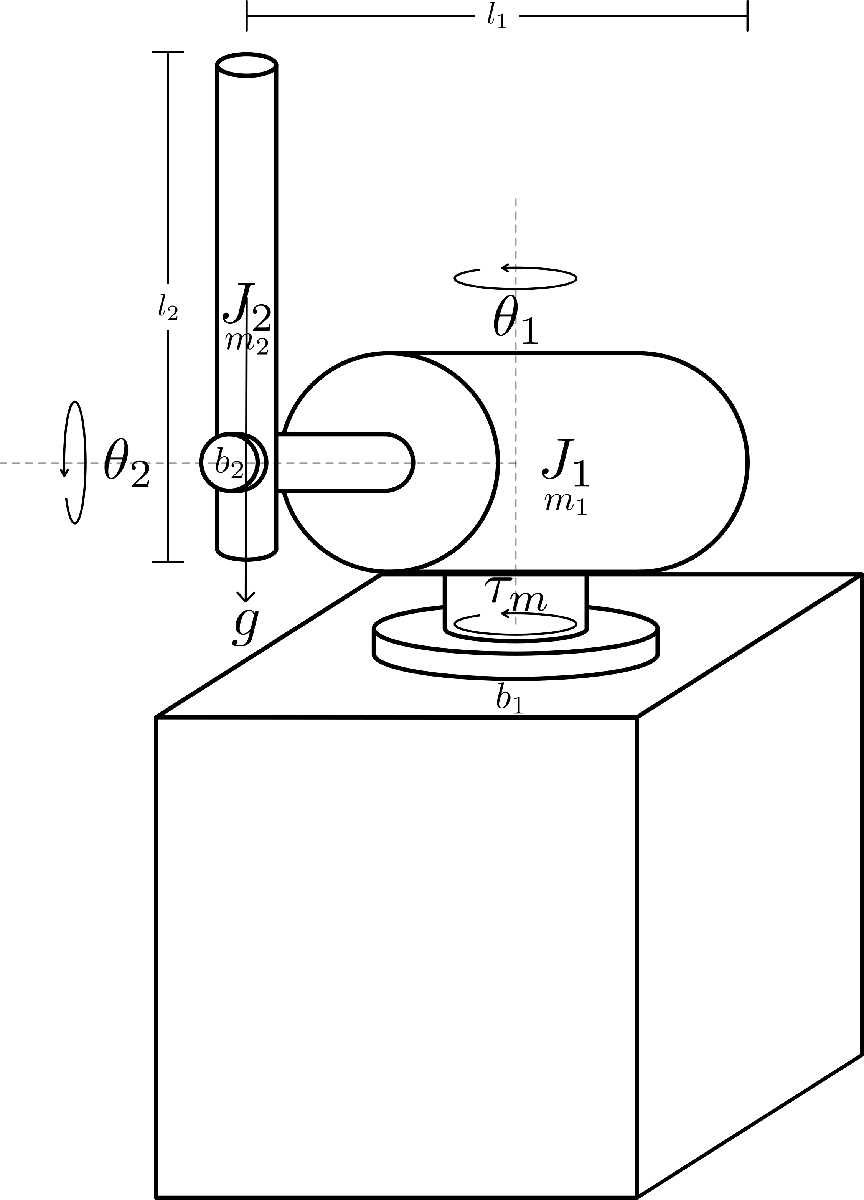

clc; clear; close all;

syms theta_1 theta_2 dtheta_1 dtheta_2 ddtheta_1 ddtheta_2 real
syms m_1 m_2 l_1 l_2 J_1 J_2 real
%syms lc1 lc2 real
syms g real
syms b_1 b_2 tau_m real

lc1 = l_1/2;
lc2 = l_2/2;

q = [theta_1; theta_2];
dq = [dtheta_1; dtheta_2];
ddq = [ddtheta_1; ddtheta_2];

The following is from lecture 12 of Modellering

90

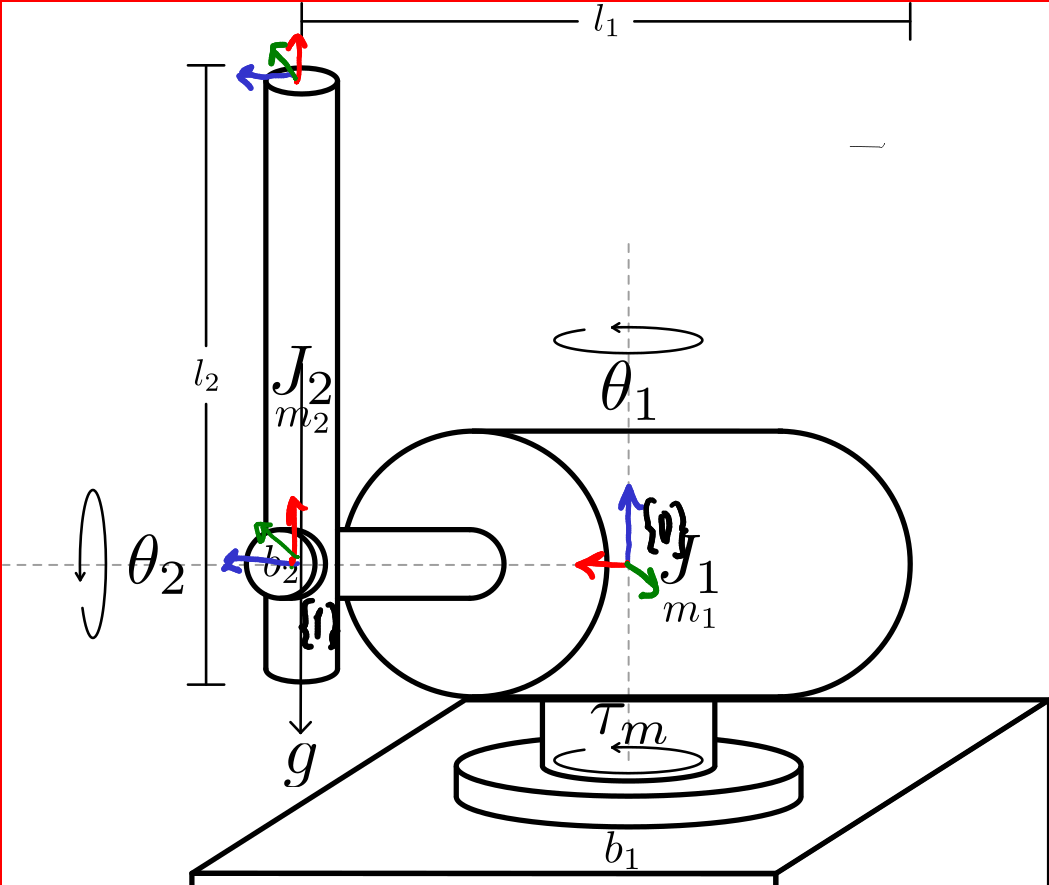

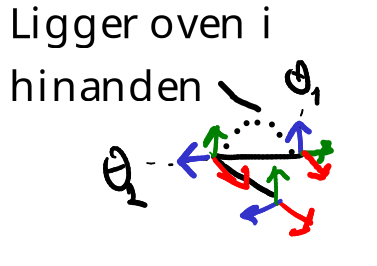

% theta_1 *0* degrees is defined to be the motors middle-point
% theta_2 *0* degrees is defined to be the pendulum laying horizontal left
% seen from the encoders point of view. Thus *90* degrees is standing
% straight up.

% DH parameters
alpha_0 = 0;
a_0 = 0;
d_0 = 0;

alpha_1 = 90; % angle from z_i to z_i+1 measured about x_i
a_1 = 0; % Offset along i x-axis
d_1 = 0; % Offset along i z-axis

alpha_2 = 0; % degrees
a_2 = l_2;
d_2 = l_1; % Since we offset along the arm, this is the translation along z_2
% And since l_1 is from the end of the encoder to the joint of the
% pendulum, we will need to divide by 2 (approximately) to go from the
% middle of the encoder (frame 1 origin) to the origin of frame 2

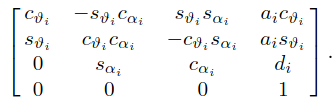

% Transformation matrix for links from DH parameters (L5 robotkinematik)
T_0_1 = [cos(theta_1) -sin(theta_1)*cosd(alpha_1)  sin(theta_1)*sind(alpha_1)  a_1*cos(theta_1);
         sin(theta_1)  cos(theta_1)*cosd(alpha_1) -cos(theta_1)*sind(alpha_1)  a_1*sin(theta_1);
                    0               sind(alpha_1)               cosd(alpha_1)               d_1;
                    0                           0                           0                 1];

T_1_2 = [cos(theta_2) -sin(theta_2)*cosd(alpha_2)  sin(theta_2)*sind(alpha_2)  a_2*cos(theta_2);
         sin(theta_2)  cos(theta_2)*cosd(alpha_2) -cos(theta_2)*sind(alpha_2)  a_2*sin(theta_2);
                    0               sind(alpha_2)               cosd(alpha_2)               d_2;
                    0                           0                           0                 1];

T_0_2 = T_0_1*T_1_2;

% Position of origo in regards to base frame
p_0 = [0;0;0];
p_0_1 = T_0_1(1:3,4);
p_0_2 = T_0_2(1:3,4)

$$p\_0\_2 = \left(\begin{array}{c} l_{1}\,\sin\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)-l_{1}\,\cos\left(\theta_{1}\right)\\ l_{2}\,\sin\left(\theta_{2}\right) \end{array}\right)$$

% Rotation matrices
R_0_1 = T_0_1(1:3, 1:3);
R_0_2 = T_0_2(1:3, 1:3);

% Position of link center in regards to base frame
p_0_c1 = R_0_1*[0;0;lc1]+p_0_1

$$p\_0\_c1 = \left(\begin{array}{c} \frac{l_{1}\,\sin\left(\theta_{1}\right)}{2}\\ -\frac{l_{1}\,\cos\left(\theta_{1}\right)}{2}\\ 0 \end{array}\right)$$

p_0_c2 = R_0_2*[-lc2; 0; 0]+p_0_2

$$p\_0\_c2 = \left(\begin{array}{c} l_{1}\,\sin\left(\theta_{1}\right)+\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{2}\\ \frac{l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{2}-l_{1}\,\cos\left(\theta_{1}\right)\\ \frac{l_{2}\,\sin\left(\theta_{2}\right)}{2} \end{array}\right)$$


% Orientation of z-axis in regards to base frame
z_0 = [0;0;1];
z_0_1 = T_0_1(1:3, 3);
z_0_2 = T_0_2(1:3, 3);

% Jacobians for each joint (L12 modellering, and L10 robotkinematik)
J_P_1 = [cross(z_0, (p_0_c1 - p_0)) [0;0;0]]

$$J\_P\_1 = \left(\begin{array}{cc} \frac{l_{1}\,\cos\left(\theta_{1}\right)}{2} & 0\\ \frac{l_{1}\,\sin\left(\theta_{1}\right)}{2} & 0\\ 0 & 0 \end{array}\right)$$

J_P_2 = [cross(z_0, (p_0_c2 - p_0)) cross(z_0_1, (p_0_c2 - p_0_1))]

$$J\_P\_2 = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1} & -\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\\ \sigma_{2} & -\frac{l_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)}{2}\\ 0 & \cos\left(\theta_{1}\right)\,\sigma_{2}-\sin\left(\theta_{1}\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(\theta_{1}\right)-\frac{l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)}{2}\\ \sigma_{2}=l_{1}\,\sin\left(\theta_{1}\right)+\frac{l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)}{2} \end{array}$$

% We will also need to find the orientational Jacobian

% To find the full expression of kinetic energy
J_O_1 = [z_0 [0;0;0]] % No joint affects the z-axis orientation of frame 1.

J_O_1 =      0     0
     0     0
     1     0


J_O_2 = [z_0 z_0_1] % Only joint 1 affects the z-axis of frame 2.

$$J\_O\_2 = \left(\begin{array}{cc} 0 & \sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{1}\right)\\ 1 & 0 \end{array}\right)$$

% To find the B-matrix, we will also need the inertia tensor of each link
% expressed in their own local frame.
% We can express the inertia tensor as a diagonal matrix using the intertia
% moments of each link.
% For each link, the axis of symmetry is either the z-axis (link 1)
% or the x-axis (link 2)
% From Modellering L8, latex page 13 we know, that the axis of symmetry is
% equal to I_y = I_x + I_z = 2*I_x or vice versa for a different symmetry
% axis.
% We use J as the symbol for intertia moment instead of I.
I_1_local = diag([J_1/2, J_1/2, J_1]);
I_2_local = diag([J_2, J_2/2, J_2/2]);

% Since we know, that E_kin can be expressed using both the B-matrix, and
% the Jacobians, we need to isolate the B-matrix from the equation at the
% top of this section. (Also pasted below for ease of use)
% B-matrix (L12 modellering)
B = simplify(m_1*J_P_1'*J_P_1 + m_2*J_P_2'*J_P_2 + J_O_1'*R_0_1*I_1_local*R_0_1'*J_O_1 + J_O_2'*R_0_2*I_2_local*R_0_2'*J_O_2)

$$B = \begin{array}{l} \left(\begin{array}{cc} \frac{J_{1}}{2}+\frac{3\,J_{2}}{4}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{8}-\frac{J_{2}\,\cos\left(2\,\theta_{2}\right)}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{8} & \sigma_{1}\\ \sigma_{1} & \frac{m_{2}\,{l_{2}}^{2}}{4}+\frac{J_{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2} \end{array}$$

E_kin_0 = simplify(1/2 * dq' * B * dq)

$$E\_kin\_0 = {\mathrm{dtheta}}_{1}\,\left(\frac{{\mathrm{dtheta}}_{1}\,\left(\frac{J_{1}}{2}+\frac{3\,J_{2}}{4}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{8}-\frac{J_{2}\,\cos\left(2\,\theta_{2}\right)}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{8}\right)}{2}-\frac{{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{4}\right)+{\mathrm{dtheta}}_{2}\,\left(\frac{{\mathrm{dtheta}}_{2}\,\left(\frac{m_{2}\,{l_{2}}^{2}}{4}+\frac{J_{2}}{2}\right)}{2}-\frac{{\mathrm{dtheta}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{4}\right)$$

% The g vector is how gravity affects in either direction from the base
% frame. The gravity only affects the system in the base frames z-axis
% going downards. So that is
g_direction = [0; 0; -g];
E_pot_0 = -(m_1*g_direction'*p_0_c1 + m_2*g_direction'*p_0_c2)

$$E\_pot\_0 = \frac{g\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2}$$

## Deriviation from corialis forces

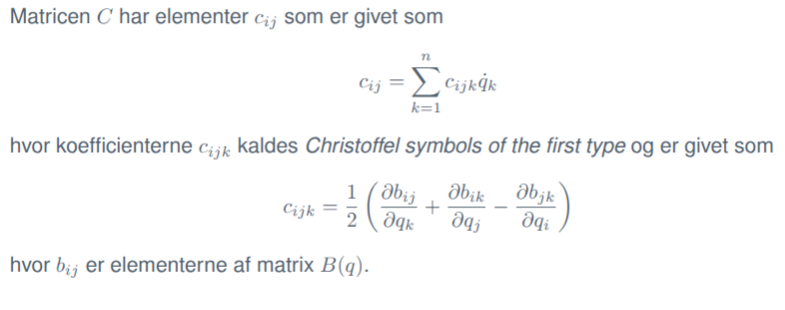

n = 2; % Number of joints
C = sym(zeros(n,n)); % Initialize C-matrix
for i = 1:n % Row of B-matrix
    for j = 1:n % Collumn of B-matrix
        for k = 1:n % Joint number
            c_ijk = 1/2 * (diff(B(i,j), q(k)) + diff(B(i,k), q(j)) - diff(B(j,k), q(i)));
            C(i,j) = C(i,j) + c_ijk * dq(k);
        end
    end
end

A Dynamical model for a robot can then be described as

We only need to calculate g(q), which is derived from E_pot as follows

g_q = [diff(E_pot_0, q(1)); diff(E_pot_0, q(2))];

% The tau vector is all generalised forces applied to the system. So that
% is input torque and friction
force_vec = [tau_m-b_1*dtheta_1; -b_2*dtheta_2] % Only joint 1 has a torque applied to it

$$force\_vec = \left(\begin{array}{c} \tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\\ -b_{2}\,{\mathrm{dtheta}}_{2} \end{array}\right)$$


%Thus
sys = B*ddq + C*dq + g_q == force_vec

$$sys = \begin{array}{l} \left(\begin{array}{c} {\mathrm{ddtheta}}_{1}\,\left(\frac{J_{1}}{2}+\frac{3\,J_{2}}{4}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+\frac{{l_{2}}^{2}\,m_{2}}{8}-\frac{J_{2}\,\cos\left(2\,\theta_{2}\right)}{4}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)}{8}\right)+{\mathrm{dtheta}}_{2}\,\left({\mathrm{dtheta}}_{1}\,\left(\sigma_{2}-\sigma_{1}\right)-\frac{{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\right)}{2}\right)+{\mathrm{dtheta}}_{1}\,{\mathrm{dtheta}}_{2}\,\left(\sigma_{2}-\sigma_{1}\right)-\frac{{\mathrm{ddtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2}=\tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\\ \left(\sigma_{1}-\sigma_{2}\right)\,{{\mathrm{dtheta}}_{1}}^{2}+{\mathrm{ddtheta}}_{2}\,\left(\frac{m_{2}\,{l_{2}}^{2}}{4}+\frac{J_{2}}{2}\right)+\frac{g\,l_{2}\,m_{2}\,\cos\left(\theta_{2}\right)}{2}-\frac{{\mathrm{ddtheta}}_{1}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{2}=-b_{2}\,{\mathrm{dtheta}}_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{l_{2}}^{2}\,m_{2}\,\sin\left(2\,\theta_{2}\right)}{8}\\ \sigma_{2}=\frac{J_{2}\,\sin\left(2\,\theta_{2}\right)}{4} \end{array}$$

% We can isolate ddq, to get the following
ddq_calculated = inv(B) * (force_vec - C * dq - g_q);

% Next we setup the state and system vectors
% State space vector
x = [q; dq];

% System vector
dx = [dq; ddq];

% Input vector
tau_vec = [tau_m; 0]; % Only joint 1 is affected by torque

f_x = [dq; ddq_calculated];
g_x = [0 0; 0 0; inv(B)]*force_vec % Why are the first two values 0? does the input not affect either of the angles?

$$g\_x = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ \frac{8\,\left(m_{2}\,{l_{2}}^{2}+2\,J_{2}\right)\,\left(\tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\right)}{\sigma_{1}}-\frac{16\,b_{2}\,{\mathrm{dtheta}}_{2}\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)}{\sigma_{1}}\\ \frac{16\,l_{1}\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)\,\left(\tau_{m}-b_{1}\,{\mathrm{dtheta}}_{1}\right)}{\sigma_{1}}-\frac{4\,b_{2}\,{\mathrm{dtheta}}_{2}\,\left(4\,J_{1}+6\,J_{2}+2\,{l_{1}}^{2}\,m_{1}+8\,{l_{1}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{2}-2\,J_{2}\,\cos\left(2\,\theta_{2}\right)+{l_{2}}^{2}\,m_{2}\,\cos\left(2\,\theta_{2}\right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=12\,{J_{2}}^{2}-4\,{J_{2}}^{2}\,\cos\left(2\,\theta_{2}\right)+8\,J_{1}\,J_{2}+{l_{2}}^{4}\,{m_{2}}^{2}+{l_{2}}^{4}\,{m_{2}}^{2}\,\cos\left(2\,\theta_{2}\right)+8\,{l_{1}}^{2}\,{l_{2}}^{2}\,{m_{2}}^{2}+4\,J_{2}\,{l_{1}}^{2}\,m_{1}+4\,J_{1}\,{l_{2}}^{2}\,m_{2}+16\,J_{2}\,{l_{1}}^{2}\,m_{2}+8\,J_{2}\,{l_{2}}^{2}\,m_{2}-8\,{l_{1}}^{2}\,{l_{2}}^{2}\,{m_{2}}^{2}\,{\sin\left(\theta_{2}\right)}^{2}+2\,{l_{1}}^{2}\,{l_{2}}^{2}\,m_{1}\,m_{2} \end{array}$$


% The state space system is then
ss_sys = simplify(f_x + g_x*tau_m) % Det er jo mega langt...

% We will need to linearize this to get the A and B vector in steady state.
% A_ss and B_ss are found by differentiating either f_x or g_x and
% evaluating at the equilibrium point (the point where the system is
% stable). The equilibrium point must relate the the state vector x and the
% input tau_m.
% The system must then be stable when:
% - theta_2 = pi/2 rad (90 degrees), as it will then be standing upright
% - dtheta_1 = dtheta_2 = 0 rad/s, as neither the motor or pendulum will
% then be moving
% - tau_m = 0, as there is then no motor input
% - theta_1 is arbitrary, as it is not relevant for the systems stability.

% We can substitute these values into f_x to check if they match.
% If it equals a 0 vector, the system is stable.
f_x_test = subs(f_x, [theta_2, dtheta_1, dtheta_2, tau_m], [pi/2, 0, 0, 0])

$$f\_x\_test = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$


% df_x/dx at equilibrium point
A_ss = [diff(f_x(1), x(1)) diff(f_x(1), x(2)) diff(f_x(1), x(3)) diff(f_x(1), x(2));
        diff(f_x(2), x(1)) diff(f_x(2), x(2)) diff(f_x(2), x(3)) diff(f_x(2), x(2));
        diff(f_x(3), x(1)) diff(f_x(3), x(2)) diff(f_x(3), x(3)) diff(f_x(3), x(2));
        diff(f_x(4), x(1)) diff(f_x(4), x(2)) diff(f_x(4), x(3)) diff(f_x(4), x(2));];

% Insert equilibrium point
A_ss = subs(A_ss, [theta_2, dtheta_1, dtheta_2, tau_m], [pi/2, 0, 0, 0])

$$A\_ss = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0\\ 0 & \frac{8\,g\,l_{1}\,{l_{2}}^{2}\,{m_{2}}^{2}}{\sigma_{2}} & -\frac{8\,b_{1}\,\left(m_{2}\,{l_{2}}^{2}+2\,J_{2}\right)}{\sigma_{2}} & \frac{8\,g\,l_{1}\,{l_{2}}^{2}\,{m_{2}}^{2}}{\sigma_{2}}\\ 0 & \sigma_{1} & -\frac{16\,b_{1}\,l_{1}\,l_{2}\,m_{2}}{\sigma_{2}} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,g\,l_{2}\,m_{2}\,\left(4\,J_{1}+8\,J_{2}+2\,{l_{1}}^{2}\,m_{1}+8\,{l_{1}}^{2}\,m_{2}\right)}{\sigma_{2}}\\ \sigma_{2}=16\,{J_{2}}^{2}+8\,J_{1}\,J_{2}+4\,J_{2}\,{l_{1}}^{2}\,m_{1}+4\,J_{1}\,{l_{2}}^{2}\,m_{2}+16\,J_{2}\,{l_{1}}^{2}\,m_{2}+8\,J_{2}\,{l_{2}}^{2}\,m_{2}+2\,{l_{1}}^{2}\,{l_{2}}^{2}\,m_{1}\,m_{2} \end{array}$$

% We assume that the effect of the input on the system 
% is constant near the equilibrium point. 
% Thus, we simply evaluate g_x at the equilibrium point to get B_ss�.
B_ss = subs(g_x, [theta_2, dtheta_1, dtheta_2, tau_m], [pi/2, 0, 0, 0])

$$B\_ss = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

% The above is not good...

We want the output y to be theta_2 (as we want to measure the angle of the pendulum)

C_ss = [0 1 0 0]; % C times x to get theta_2
D_ss = 0; % The input torque does not directly affect theta_2

y = C_ss*x + D_ss*tau_m

$$y = \theta_{2}$$

## Frequency domain model

We can now convert to the frequency domain to get the transfer function G(s).

syms s
G = C_ss*inv(s*eye(4)-A_ss)*B_ss+D_ss % The result is 0. That is not correct.

$$G = 0$$

term1 = inv(s*eye(4)-A_ss)

term2 = C_ss*term1

$$term2 = \left(\begin{array}{cccc} 0 & \frac{1}{s} & 0 & 0 \end{array}\right)$$

term3 = term2*B_ss % The issue must be with the B_ss vector. Makes sense, since it is filled with 0's

$$term3 = 0$$

## Time domain models

We now try to write up state space models for the system, that can later be converted to transfer functions.

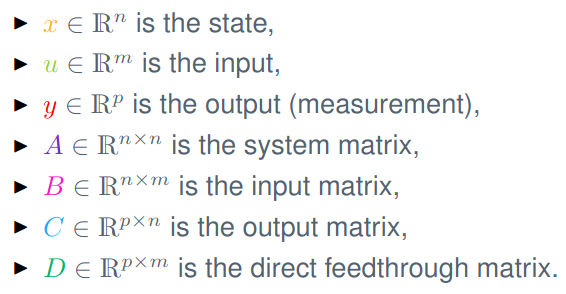

We will want to use the torque $\tau_m$ as an input and get the angular velocity of the pendulum $\dot{\theta_2 }$ as an output. We want this to be zero. We also want the angle $\theta_2$ to be 180 degrees (but this is for another time...)

% State space vectors
x_1 = [theta_1; dtheta_1];
x_2 = [theta_2; dtheta_2];
x = [x_1; x_2];

% System vectors
dx_1 = [dtheta_1; ddtheta_1];
dx_2 = [dtheta_2; ddtheta_2];
dx = [dx_1; dx_2];
